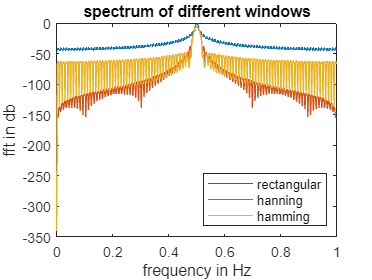

%question 1.1
figure;
N=500;
freq=(0:N-1)./N;
plot(freq,20*log10(abs(fftshift(fft(rectwin(100),N)/100))))
hold on
plot(freq,20*log10(abs(fftshift(fft(hanning(100),N)/100))))
hold on 
plot(freq,20*log10(abs(fftshift(fft(hamming(100),N)/100))))
hold off
title('spectrum of different windows')
xlabel("frequency in Hz")
ylabel("fft in db")
legend('rectangular','hanning','hamming','Location','southeast')

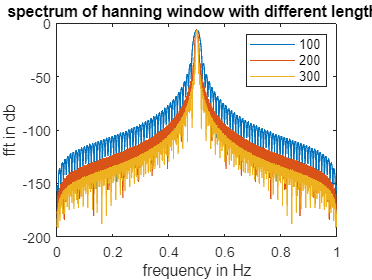

%question 1.2
figure;
N=1024;
freq=(0:N-1)./N;
plot(freq,20*log10(abs(fftshift(fft(hanning(100),N)/100))))
hold on
plot(freq,20*log10(abs(fftshift(fft(hanning(200),N)/200))))
hold on 
plot(freq,20*log10(abs(fftshift(fft(hanning(300),N)/300))))
hold off
legend('100','200','300')
title("spectrum of hanning window with different lengths")
xlabel("frequency in Hz")
ylabel("fft in db")

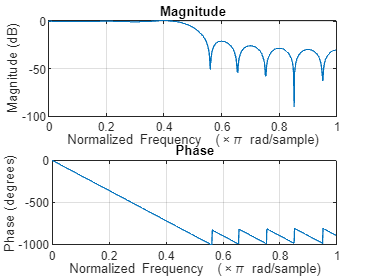

%Question 2
figure;
n=20;
wc=1/2;
b=fir1(n,wc,'low',rectwin(21));
freqz(b)

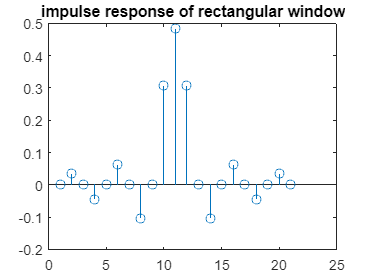

stem(b)
title("impulse response of rectangular window")

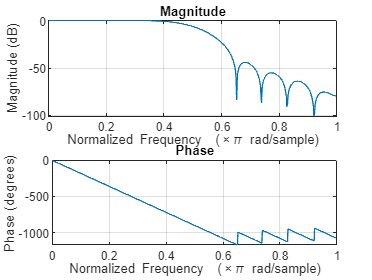

figure;
n=20;
wc=1/2;
b=fir1(n,wc,'low',hanning(21));
freqz(b)

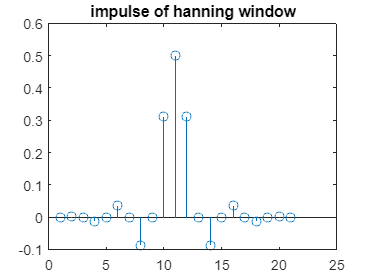

stem(b)
title("impulse of hanning window")

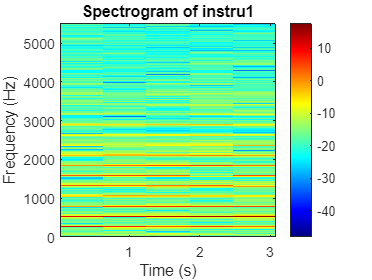

[y1, Fs] = audioread('instru1.wav');
window_length = 7250;  % Window size in samples
overlap = 512;         % Overlap between consecutive windows in samples
nfft = 7250;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f, t] = spectrogram(y1, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of instru1');
colorbar;  % Add a colorbar to show magnitude values


figure;
N=length(y1);
fft_opera=abs(fft(y1));
freq_axis=Fs*((0:N-1)/N);
[~, idx]=max(fft_opera(2:end));
fundamental_frequency=freq_axis(idx)

fundamental_frequency = 524.0297

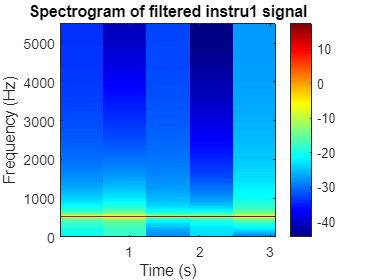

n=1000;
wc=[(fundamental_frequency-10)*2/Fs (fundamental_frequency+10)*2/Fs];
b=fir1(n,wc);
y=filter(b,1,y1);

window_length = 7250;  % Window size in samples
overlap = 512;         % Overlap between consecutive windows in samples
nfft = 7250;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f, t] = spectrogram(y, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of filtered instru1 signal');
colorbar;  % Add a colorbar to show magnitude values


output_file='filtered_instru.wav';
audiowrite(output_file,y,Fs);
sound(y,Fs)